# マルチモーダル学習×ベイズ最適化（村田）

 
s = settings;
s.matlab.fonts.editor.title.Style.PersonalValue = {'bold'};
s.matlab.fonts.editor.title.Color.PersonalValue = [0 0 255 1];

# 0. ワークスペースの掃除・開いている図の削除

matlabでは

clcでコマンドラインの履歴の削除

clearでワークスペースの変数の削除. 

close all hiddenで最小化されているグラフも含めて全て削除

することが出来ます. 

 
clc;
clear;
close all hidden;

# 1. Excelデータの取り込み

RawDataクラスによってExcelデータを取り込みます. 

 
data1 = "20251114"; %trainData
data2 = "20251117"; %testData

dataCreator = RawDataCreatorWave();

%trainVF for Void Fraction data, trainPr for Pressure difference data
trainVF = dataCreator.createVF(data1,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。


trainPr = dataCreator.createPr(data1,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。


testVF = dataCreator.createVF(data2,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。


testPr = dataCreator.createPr(data2,100, Conditions.c12a, Labels.c12a_normal, true, CorrectConditions.c12a_liquidChange);

情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。
情報: 8列目のデータ (pressure8) を使用しました。


rawAllData= RawAllDataBeforeFormatWave([trainVF, trainPr, testVF, testPr]);

%前処理インスタンスの作成. ここでは計測周波数をそろえ, ボイド率の補正を行う. 
preProcessor = PreProcessorBeforeFormatWave({@intervalUniformerWave, @correctWithCapacitanceBaseWave});
%前処理の実行
trainVF = preProcessor.process(trainVF,rawAllData);

trainPr = preProcessor.process(trainPr,rawAllData);
testVF = preProcessor.process(testVF,rawAllData);

testPr = preProcessor.process(testPr,rawAllData);

# 2. データ拡張(スライディングウィンドウ法)

流石に一本の時系列データだけでは不足しているため, 一個ずらしのx点で切り取ってデータを増やします. 

 
stride = 1; %各データごとに何計測点飛ばすか. ふつうは1
dataWidth = 400; % データ幅. ここは調整して良い. いつもは300で統一
interval = 0; %データをいくつ飛ばしでdataWIdth点だけ取るか. ふつうは0

%optionの作成 
dataFormatterOption = DataFormatterOptionWave(stride,dataWidth,interval);
%dataFormatter本体を作るクラスにoptionを流し込む (この一段は拡張性のために一応2021年に実装したけど, いらなかったかも)
dataFormatterCreator = DataFormatterCreatorWave(dataFormatterOption);
%optionにしたがってデータをデータ拡張してくれるインスタンスの作成
dataFormatter = dataFormatterCreator.create();

%データ拡張を実施
trainVF = dataFormatter.Format(trainVF);
trainPr = dataFormatter.Format(trainPr);
testVF = dataFormatter.Format(testVF);
testPr = dataFormatter.Format(testPr);

# 3. 訓練及びテストデータ作成(分類)

適宜splitを使ってその日のデータの内いくつかを切り取ることも出来ます. 

 
trainTestDataCreator = TrainTestDataCreatorWave();

[train, test] = trainTestDataCreator.createAndPreProcessMultimodalWaveData([trainVF trainPr],[testVF testPr], @cellInputStandardizeWave);

# 4. 訓練設定(分類)

訓練を始める前に

- どんな方法で訓練を行うのか, 

- そもそも深層学習の層をどのように組むのか

を決定します. 

 
initialLearnRate = 0.001;
maxEpoch = 30; % データ全てを何周したら訓練を終わらせるか. 1周は全データが深層学習に一回は入力されたことを意味する(厳密には異なるが)
miniBatchSize = 64;% 一回で深層学習にどれだけのデータを食わせるか. 確率勾配法の肝. まぁとりあえず64でいいかという感じ. 
frequency = 25; % 訓練何回ごとに検証データを入力して上手く学習が進んでいるのかどうかを判断する. 
trainRepeatAmount = 1;% 何回訓練と精度確認を行うか. 精度上昇の効果が見られたとしてもそれがちゃんと再現性のある結果なのかどうかを判断するときに使う.
                                            %x回まわして殆ど全ての場合で精度向上が見られたらokみたいな. 
toleranceTimesForNotImproving = 20; % 訓練中に検証データを入れて, この回数だけ精度の向上が無かった場合には訓練を修了する. 

% どんな設定で訓練を行うのかを保存するインスタンスを作成 
classificationTrainOptionCreator = TrainOptionCreatorWave(train,test);
option = classificationTrainOptionCreator.createNormalTrainOptionWave(initialLearnRate, maxEpoch,miniBatchSize,frequency,trainRepeatAmount,toleranceTimesForNotImproving);

% どんな層の構成(reluとかdropoutとかもここの内部で決める)で訓練を行うのかを保存するインスタンスを作成. 
% カスタム関数を使用する場合は内部の実装の関係上, 出力層(regression層やclassification層)を持つことは許されていないので変更の必要あり.
layerSettingCreator = LayerSettingCreatorWave(train,test);

inputsize = 2; % 入力の数. 今は1. 例えば, ボイド率計のデータだけでなくて, 温度センサのデータも入れてみたいとなるとここは2になる. 
hiddenUnitSize = 320;

%layer = layerSettingCreator.createSingleLSTMLayer(inputsize, hiddenUnitSize);
layer = layerSettingCreator.createSingleLSTMLayerForCustomLossFunc(inputsize,hiddenUnitSize);

# 5. 訓練開始(分類)

結構時間かかるので注意

※訓練モニターをもっとよくしたい場合: https://jp.mathworks.com/help/deeplearning/ug/monitor-custom-training-loop-progress.html#mw_44de1bac-06f9-4426-91dd-c22b43c65fda. 

 
% 訓練を担当するクラス ２
trainActivator = TrainActivatorWave(train,test,option,layer);

prefix = "helloWorld/";
folderName = append(prefix,"20260118_04/");

result = trainActivator.customLossFuncForMultimodalActivate(trainActivator, "softmax",@multiCrossEntropyLoss,folderName);

%result = trainActivator.activateMultimodal(trainActivator, folderName);　%標準な学習（単一入力）に使用

# 6. 結果の表示(分類)

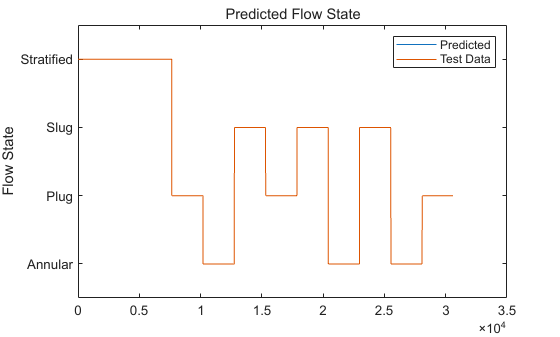

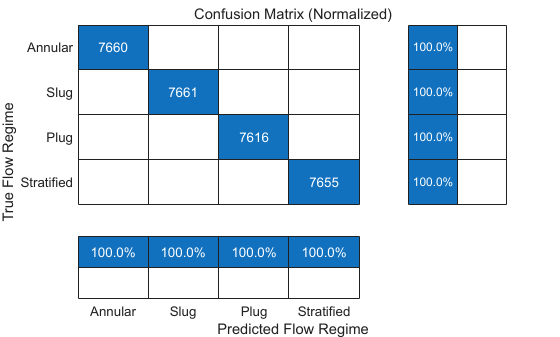

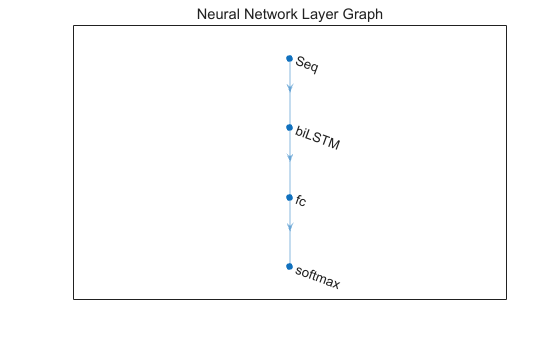

クラス 'TrainResult' のメソッド、プロパティまたはフィールド 'trainAccuracy' が認識されません。

エラー: ResultDisplayerWave/displayResult (行 39)
            trainAcc = obj.result.trainAccuracy;
            ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

 

resultDisplyer = ResultDisplayerWave(result,option);
resultDisplyer.displayResult(folderName);

# 7. それでは損失関数を変えてみましょう. 

ここまでは損失関数はcrossrntropyの通り, シンプルなクロスエントロピー誤差でやっていました. ところで, 深層学習にはoverConfidenceという現象があります. モデルが自信過剰になるものですね. あいまいなところはあいまいで良いのに... 

こういうのに対して損失関数から攻める方法があります. (cf. [https://zenn.dev/bilzard/scraps/d3875d0c5c5e92)](https://zenn.dev/bilzard/scraps/d3875d0c5c5e92))

というわけで, Label Smoothingを使ってみましょう.

なお, 他のloss func: https://knto-h.hatenablog.com/entry/2018/10/09/170000

まずは損失関数の定義からです. 

※定義自体はここではなく, Class->DeepLearning->TrainNet->classification->lossFunc->singleClasssificationに書いてください. (書いた)

次のように損失関数は定義します. 

%{
function func = labelSmoothing(outputLayerName)
arguments
    outputLayerName string
end
%LABELSMOOTHING 正解ラベルの値を1でなく1よりも少しだけ小さな値にすることで、logitが発散するのを抑制する手法。
% cf. https://zenn.dev/bilzard/scraps/d3875d0c5c5e92
% 学習率と連動させてオンライン化するのも面白いかもね. https://qiita.com/T-STAR/items/a3bdcd1ae00150fe1402
function [loss,gradients,state] = labelSmoothingCore(net,trainData,label)
        [predictedLiquid, state] = forward(net,trainData,Outputs=[outputLayerName]);
        %Loss Functionを改造したい時はこの一行を変えてください. ================================
        %predictedLiquid は条件数(12条件とか)*MiniBatchSize(64とか)のdlArrayです. 
        %labelも同じです. どちらもone-hot-表現で出てきます. 
        noise = 0.3; % これ, 色々変えてみてください.  正解クラス以外にどれだけノイズを分配するかです. 
        modifiedTarget = label*(1-noise)+noise/size(label,1);
        lossBeforeMean = -sum((modifiedTarget).*log(predictedLiquid));
        loss = mean(lossBeforeMean); % ミニバッチのため,平均化
        %======================================================================================
        gradients = dlgradient(loss,net.Learnables);
    end
func = @labelSmoothingCore;
end


それではこの損失関数を使った場合の結果を見てみましょう. 

 
% 訓練を担当するクラス 
trainActivator = TrainActivator(train,test,option,layer);
prefix = "helloWorld/";
folderName = append(prefix,"test-3-labelSmoothing/");
% 結果が格納されたクラス (カスタム損失関数の時は関数変わります)
result = trainActivator.customLossFuncActivate("softmax",@labelSmoothing,folderName);

# ８．結果の表示

損失関数を変化させた場合の結果の表示をしましょう. 

 
resultDisplyer = ResultDisplayer(result,option);
resultDisplyer.displayResult(folderName);
%}

どうでしょうか, 何か変わりましたかね? 私は確認していないのでここからはあなたが責任を持って結果を解析してみてください. 